## **Practice 8**

Standard Error and Correlation

function err = errorCorr(a, b, eq, no)
% for calculating any polynomials EXCEPT multivariable polynomials
% a is array x, b is array y, eq is syms with var x , y, no is no. of
% polynomials
    
    sr = 0;
    st = 0;

    for m = 1:length(a)
        A = a(m);
        syms x
        sr = sr + (b(m) - (subs(eq, x, A)))^2;
        st = st + (b(m) - mean(b))^2;
    end

    % Finding r2 (r2 = (st - sr)/st)
    r2 = sqrt(1 - (sr/st));

    % Finding synx (syx = sqrt(sr/(n- (m+1))))
    synx = sqrt(sr/(length(b) - (no + 1)));

    % Return both synx, r2
    err = [double(synx), double(r2)];
end

Coefficient of multiple linear regression

% tval = 0:5:30;
% t = [tval tval tval]';
% c = [0 0 0 0 0 0 0 10 10 10 10 10 10 10 20 20 20 20 20 20 20]';
% y = [14.6 12.8 11.3 10.1 9.09 8.26 7.56 12.9 11.3 10.1 9.03 8.17 7.46 6.85 11.4 10.3 8.96 8.08 7.35 6.73 6.20]';

%  Step 2: Solve for a to create fitted function
% z = [ones(size(t)) t c];  % เป็น 2 ตัวแปร
% a = (z'*z)\(z'*y);

%  Step 3: Create fitted function
% fitted_func = @(temp, concent) a(1) + a(2).*temp + a(3).*concent;

%  Step 4: Eval the value
% fprintf('Oxygen estimated to be %f\n', fitted_func(12, 15));


function [coefficients] = multipleLinearRegression(x, y, z)
% remember to flip x, y, and z
    a = [ones(size(x)) x y]; % create matrix of 1s size x
    b = (a'*a)\(a'*z); % find coefficient
    coefficients = b;
end

## Practice 9

Interpolate functions

function x_interp = interpolatePolynomial(x, y, degree, x_interp)
    if length(x) ~= length(y) || degree >= length(x)
        error('Input data is invalid for interpolation');
    end

    % Create the Vandermonde matrix for the given degree
    A = zeros(length(x), degree + 1);
    for i = 1:(degree + 1)
        A(:, i) = x.^(degree + 1 - i);
    end

    % Solve for the coefficients using left division
    coefficients = A \ y;

    % Evaluate the polynomial at the interpolation points
    B = zeros(length(x_interp), degree + 1);
    for i = 1:(degree + 1)
        B(:, i) = x_interp.^(degree + 1 - i);
    end
    y_interp = B * coefficients;

    % x_interp now contains the interpolated values of x
    x_interp = y_interp;
end

find coefficients 

function coefficients = betterpolyfit(x, y, degree)
    if length(x) ~= length(y) || degree >= length(x)
        error('Input data is invalid for interpolation');
    end

    % Create the Vandermonde matrix for the given degree
    A = zeros(length(x), degree + 1);
    for i = 1:(degree + 1)
        A(:, i) = x.^(degree + 1 - i);
    end

    % Solve for the coefficients using left division
    coefficients = A \ y;
end

Inverse interpolation

function val = inversePol(x, y, given_y)
    n = length(x);
    p = polyfit(x, y, n-1); % Fitting polinomial to n - 1 degree
    
    root = roots([p(1:end-1) p(end)-given_y]); % 
    root = root(imag(root) == 0); % Filter out imaginary Parts

    val = root;
end

## Practice 10

function I_trapz = comp_trapz(f, a, b, n)
    % func: The function to be integrated
    % a: Starting point of the interval
    % b: End point of the interval
    % n: Number of segments

    % Calculate the step size
    h = (b-a)/n;

    x = linspace(a, b, n + 1);      % Generate values of x including both endpoints
    fx = 2*sum(f(x(2:end-1)));
    I_trapz = (h/2) * (f(a) + fx + f(b));
end

Simpson Integration

function I_simpson = comp_simpson(f, a, b, n)
    % if n = even number and more than 1
    % apply simpson 1/3
    if mod(n, 2) == 0 && n > 1
        h = (b-a)/n;
        x = a:h:b;
        disp(f(x(2:2:end-1)))
        I_simpson = (h/3) * ( f(a) + 4*f(x(2:2:end-1)) + 2*sum(f(x(3:2:end-2))) + f(b) );
    
    % 3 points -> 3/8 rules
    elseif n == 3
        h = (b-a)/n;
        x = a:h:b;
        I_simpson = ( (b-a)/8 ) * ( f(a) + 3*f(x(2)) + 3*f(x(3)) + f(b) );

    elseif n > 3
        disp('Odd number of intervals entered. Combining 1/3 and 3/8 rule.');
        h = (b-a)/n;
        x = a:h:b;
        I_simpson = ((h/3) * ( f(a) + 4*f(x(2:2:end-4)) + 2*sum(f(x(3:2:end-5))) + f(x(end-3)) )) + ( (b-x(end-3))/8 ) * ( f(x(end-3)) + 3*f(x(end-2)) + 3*f(x(end-1))+ f(b) );
    end
end

function integral = unequal_trapz(x, y)
    %{
    Implements the trapezium rule for unequally spaced data:
    A = (h1/2)*(f(x0)+f(x1)) + (h2/2)*(f(x1)+f(x2)) + ...
    %}

    % Check if vectors are the same length and are ordered
    if length(x) ~= length(y)
       % If vectors are different lengths display a message to the user
       disp('2 vectors are in different length')
    else
        n = length(x);

        % Initialize the integral
        integral = 0;
    
        % Calculate the integral using the trapezoidal rule
        for i = 1:n-1
            h = x(i+1) - x(i);
            integral = integral + 0.5 * h * (y(i) + y(i+1));
        end
    end
end

function integral = sort_unequal_trapz(x, y)
    % x: Vector of x-values (unequal spacing)
    % y: Vector of corresponding function values

    % Check if the number of data points in x and y is the same
    if length(x) ~= length(y)
        error('The number of data points in x and y must be the same.');
    end

    n = length(x);  % Number of data points

    % Sort the data in ascending order of x
    % sort(x, 'descend'); for descend
    [x, idx] = sort(x);         % ascending value of x
    y = y(idx);                 % x indices stored in idx, get corresponding y of previous x

    % Initialize the integral
    integral = 0;

    % Calculate the integral using the trapezoidal rule
    for i = 1:n-1
        h = x(i+1) - x(i);
        integral = integral + 0.5 * h * (y(i) + y(i+1));
    end
end

## Practice 11

Monte Carlo

function [monte_int] = MonteCarloIntegration(max_x, min_x, max_y, min_y, func, tol)
    
    % domain comes from the integral area.

    n = 0;
    error = 5000;
    samples = 100000;
    x = (max_x - min_x).*rand(samples,1)+min_x;
    y = (max_y - min_y).*rand(samples,1)+min_y;
    value = [];
    
    while n < samples || tol < error
        n = n+1;
        value(end + 1) = (max_x-min_x).*(max_y-min_y)*func(x(n),y(n));
        if length(value) >= 2
            error = value(end) - value(end-1);
        end
        if length(value) == n
            disp('Maximum number of iterations reached. Result may be inaccurate.')
            break
        end
    end
    monte_int = sum(value)/n;
end

Romberg

function A = romberg(func, a, b, tol)
    i_max = 1000;
    n = 1;
    i(1,1) = trapezium(func, a, b, n);          % เพราะ Romberg พื้นฐานมาจาก Richardson Extrapolation และ Richard ก็อิงมาจาก Trapz Rule อีกที
    j = 0;
    while j < i_max
        j = j + 1;
        n = 2^j;
        I(j+1, 1) = trapezium(func, a, b, n);
        for k=2:j+1
            jj = 2+j-k;
            I(jj,k) = ( ((4^(k-1)) * I(j+1 - (k-2), k-1)) - I(j- (k-2), k-1) )/ ((4^(k-1)) -1) ;% Romberg formula.
        end
        ea = abs((I(1, k) - I(2, k-1))/ I(1,k) ) * 100  ;        % Approximate percentage error.
        if ea < tol               % If statement that breaks the loop if the error is less than the tolerance.
            disp('error less than the tolerance. STOP!')
            break
        end
    end
    A = I(jj,k);                   % Final output.
    if j == i_max                  % If maximum iterations are reached display a warning to the user.
        disp('max iteration reached')
    end
end

Trapezium

function area = trapezium( f, a, b, n )
%{
Implements the composite trapezium rule:
A = (h/2)*(f(x0)+2*f(x1)+2*f(x2)+...+f(xn))
%}
format rational
% Step size
h = (b - a)/ n ;

format default
% x-values at which to evaluate function
x = a : h : b ;

% Vectorised formula for integral
area = (h/2) * ( f(a) + (2 * sum( f(x(2:end-1)) )) + f(b)) ;
end

## Practice 12

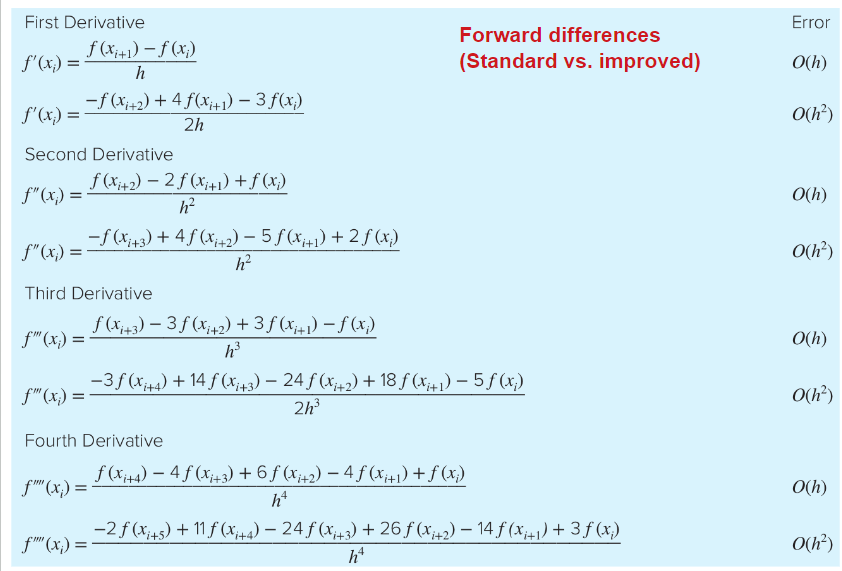

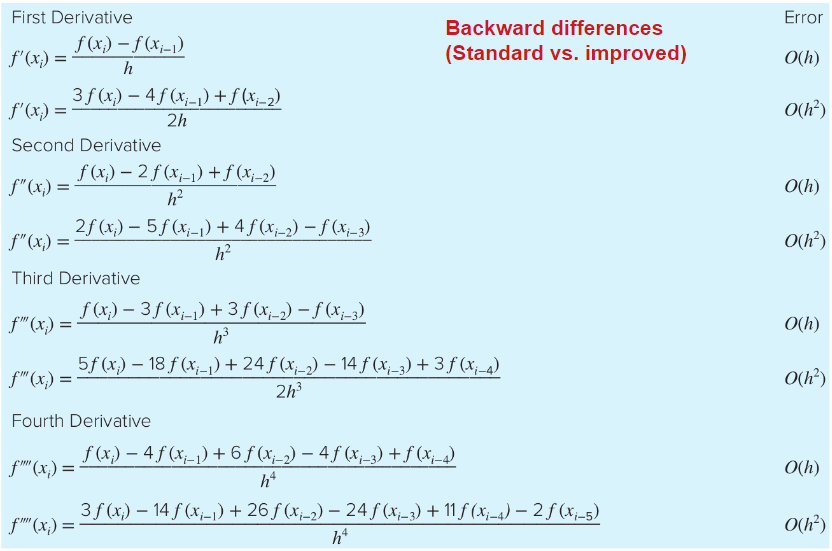

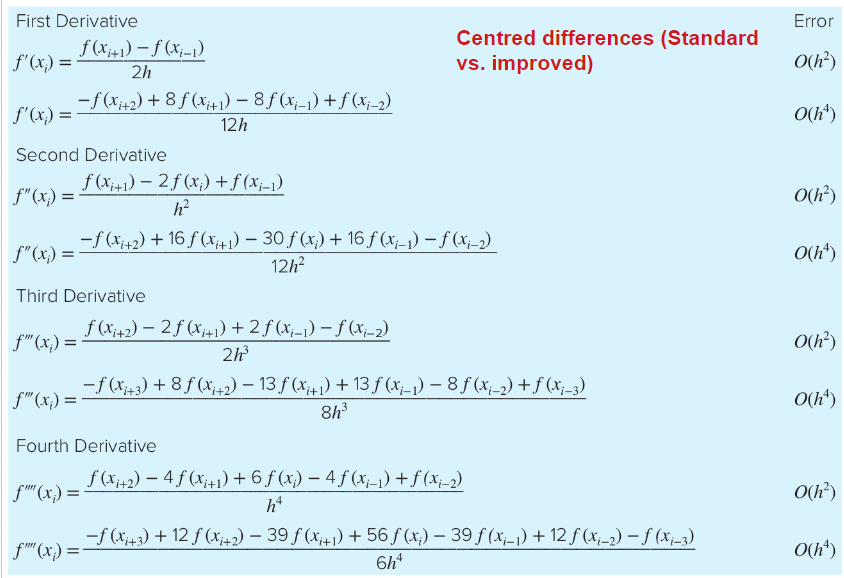

## Practice 13

Euler ODE

function [answ] = eulerOde(y0, h, tstart, tend, eq)
% y0 is y at t = 0 (given)
% tstart is start t
% tend is end t
% h is step size
% eq is given equation in syms with y and t as variables
    y1 = y0;
    yArr = [];
    yArr(2,1) = y0;
    for n = tstart:h:(tend-h)
        syms y t
        ynew = y1 + subs(eq, [y, t], [y1, n])*h;
        yArr(2,end+1) = ynew;
        y1 = double(ynew);
    end
    yArr(1,1) = y1;
    answ = yArr;
end

Heuns ODE without iteration

% Heuns ODE without iteration
function [answ] = heunsOde(y0, h, tstart, tend, eq)
% y0 is y at t = 0 (given)
% tstart is start t
% tend is end t
% h is step size
% eq is given equation in syms
    y1 = y0;
    yArr = [];
    yArr(2,1) = y0;
    for n = tstart:h:(tend-h)
        syms y t
        ynew = y1 + subs(eq, [y, t], [y1, n])*h;
        y1 = double(y1 + (subs(eq, [y, t], [y1, n]) + subs(eq, [y, t], [ynew, n + h]))/2 * h);
        yArr(2,end+1) = y1;
    end
    yArr(1,1) = double(y1);
    answ = yArr;
end

Heuns ODE with iteration

% Heuns ODE with iteration
function y_array = HeunIterativeMethod(init, start, final, step, dy, tol)

t = start:step:final;
y_array =  [ init ]; 

    for j = 1:length(t)-1
        init_slope = dy(t(j),y_array(j));  % first initial slope
        init_next_y = y_array(j) + ( init_slope * step );   % first predicted y-val.
        iter = 0;
        while iter < 100
            next_slope = dy(t(j)+step,init_next_y);   % slope at first predicted y-val
            avg_slope = ( init_slope + next_slope )/2;   % average of initial slope and slope at firstly predicted y-val. 
            new_next_y = y_array(j) + ( avg_slope * step ); % newly predicted y-val.
            err = ( abs(( new_next_y - init_next_y ) / new_next_y ) ) * 100;  % comparing the relative error between two predicted y.
            if err < tol          % if the error is lower than the tolerance,
                y_array(end+1) = new_next_y;    % the newly predicted y becomes the approximation, adding it to the array.
                break
            else                  % or else, the newly predicted y become the first predicted y-val.
                init_next_y = new_next_y;
                iter = iter + 1;
            end
        end
        disp(iter)
    end
end

Runge Kutta ODE

% function for Runge - Kutta (RK) Method
function [y_values] = rungeKutta4(yInitial, h, t_start, t_end, ode_equation)
    % Initialize arrays to store time and y values
    t_values = t_start:h:t_end;
    y_values = zeros(size(t_values));
    
    % Set the initial value
    y_values(1) = yInitial;

    % Perform the Runge-Kutta integration
    for n = 1:(length(t_values) - 1)
        tt = t_values(n);
        yy = y_values(n);
        % Calculate the four slopes (k1, k2, k3, k4)
        syms y t
        k1 = h * subs(ode_equation, [t, y], [tt, yy]);
        k2 = h * subs(ode_equation, [t, y], [tt + h/2, yy + k1/2]);
        k3 = h * subs(ode_equation, [t, y], [tt + h/2, yy + k2/2]);
        k4 = h * subs(ode_equation, [t, y], [tt + h, yy + k3]);
        
        % Update y using the weighted average of the slopes
        y_values(n + 1) = yy + (k1 + 2*k2 + 2*k3 + k4)/6;
    end
end